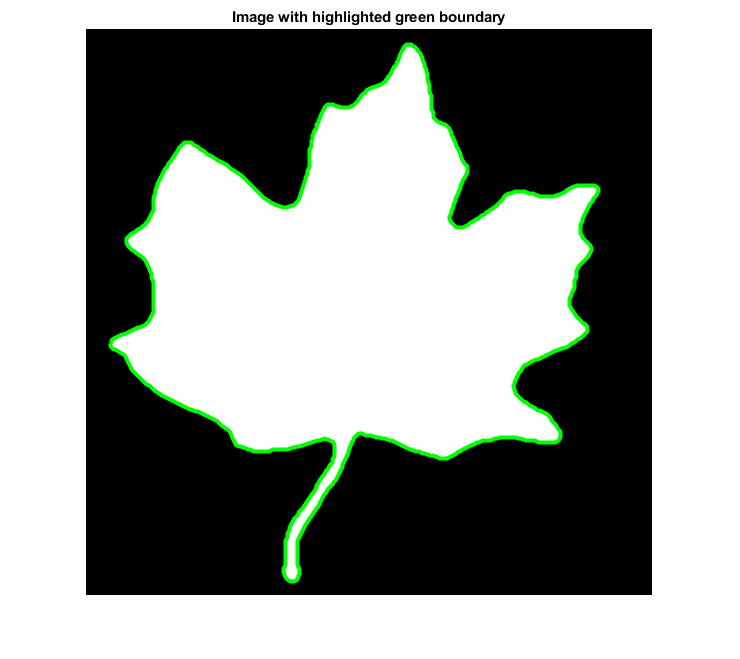

close all
clearvars
% ======================================

img = imread('Mapleleaf.tif');

% Trace region boundaries in a binary image
boundaries = bwboundaries(img);
boundary   = boundaries{1};

% Plotting the resultant image

figure;
imshow(img);
title('Image with highlighted green boundary');
hold on
plot(boundary(:,2),boundary(:,1),'g','LineWidth',3);

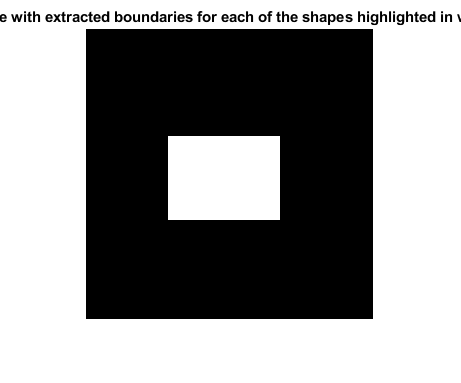

close all
clearvars
% ===================================

img = imread('Rect.png');

img_gray = rgb2gray(img);
img_gray = im2double(img_gray);

% Extracts boundaries of the image.

boundaries = bwboundaries(img_gray);

figure;
imshow(img);
title('Image with extracted boundaries for each of the shapes highlighted in white');
hold on

for i = 1 : size(boundaries,1)
    b = boundaries{i};
    plot(b(:,2),b(:,1),'b.-','Linewidth',3);
end

% -----------------------

img_bw = imbinarize(img_gray);
imshow(img_bw)

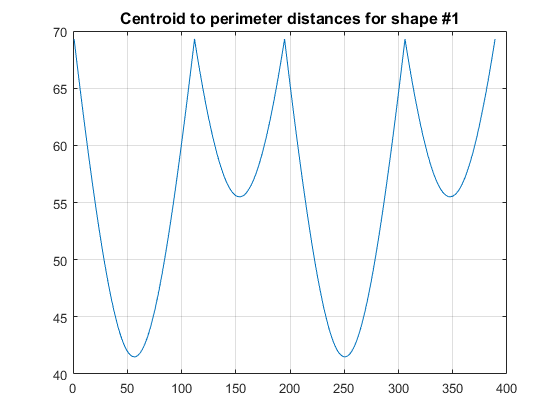


Measurements = regionprops(img_bw,'Centroid');

numRegions = length(Measurements);

for i = 1 : numRegions
	    
    % Get x and y
    x = boundaries{i}(:, 2);
    y = boundaries{i}(:, 1);

	% Get the centroid
    xCenter = Measurements(i).Centroid(1);
    yCenter = Measurements(i).Centroid(2);
    
    % Compute distances
    distances = sqrt((x - xCenter).^2 + (y - yCenter).^2);
    
	% Plot the distances.
    figure;
	plot(distances);
    grid on;
	message = sprintf('Centroid to perimeter distances for shape #%d', i);
	title(message, 'FontSize', 12);
 
end

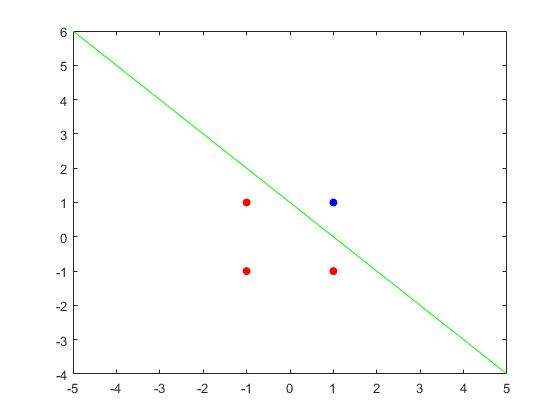

% Learning
close all
clearvars
% =======================================

x = [1, -1, -1, 1; 1, 1, -1, -1];
 
target = [1; -1; -1; -1];

w = [0; 0];
b = 0;
alpha = 0.1;

epoch = 0;
cnt = 0;
flag = 1;
while flag == 1
    cnt = 0;
    for i = 1:size(x, 2)
        h = sign( b + sum(x(:, i) .* w) ); 
        
        if h ~= target(i)
            w = w + alpha * target(i) * x(:, i);
            b = b + alpha * target(i);
        else
            cnt = cnt + 1;
        end
    end
    
    epoch = epoch + 1;
    if epoch > 100, flag = 0; epoch =0 ; end
    
    if cnt == 4, flag = 0; end
end


X = linspace(-5, 5);
Y = (w(1)*X + b) / -w(2);
figure,
plot(X, Y, 'g'), hold on
scatter(x(1, 1), x(2, 1), 'blue', 'filled')
scatter(x(1, 2:end), x(2, 2:end), 'red', 'filled')